- **Joint probablity **

Consider the example of joint probability in 2022_Week_2_Ch.2 .., 


$$f(x,y) =
\begin{cases}
2, \  \ x>0, y>0, x+y < 1 \\
0, \ \   \ \  \  \  \ other wise  
\end{cases}
$$


we study this example in matlab. First generate sample points to satisfy the given joint probability function. My plan to generate the pdf defined is 

 1) for the x, y range , make a grid 

 2) at each grid the value is equal to 2

 3) the prob to be 1, normalize it by divide the sum 

clear all; clc
dx =0.001; dy = 0.001;   % make grids , step size
x =0:dx:1;               % 0 < x <1
y =0:dy:1;               % 0 < y < 1
zsum =0;                 % initial total joint sample point
for i = 1: size(x,2)
    for j = 1: size(y,2)
        if x(i) + y(j) < 1 
            z(i,j) = 2;    % f(x,y) = 2
        else
            z(i,j) =0;
        end
        zsum =zsum+ z(i,j);
    end
end
Total_prob = zsum*dx*dy   % normalize to satify the total prob to be one

 1)** marginal prob**

 The marginal probability is 

                               
$$f(x)  = \int_{0}^{\infty} f(x,y) dy$$


so in matlab 

%% marginal probability 
n_x=[ ];    % zero for summation 
for i = 1: size(x,2)
    n_x(i) = sum(z(i,:));  % sum of all z(i,y) along y direction 
end
prob_x  =n_x / size(y,2);  % normalize
figure(1)
subplot(2,1,1)
plot(x,prob_x)
title(' pdf of x')
xlabel('x')

n_y=[ ]; 
for i = 1: size(y,2)
    n_y(i) = sum(z(:,i)); % sum of all z(x,i) along x direction 
end
prob_y  =n_y/ size(y,2);

subplot(2,1,2)
plot(y,prob_y)
title(' pdf of y')
xlabel('y')

2) **expectation**

%% expectation
ExpX=0;   % expectation of x
for i =1:size(x,2)
    ExpX = ExpX + x(i)*prob_x(i);
end
ExpX/size(x,2)

ExpY = 0;  % expectation of y
for i =1:size(x,2)
    ExpY = ExpY + y(i)*prob_y(i);
end
ExpY/size(y,2)


- **Convolution integral  - signal **

 In control or signal processing, the convolution integtal may be useful. Conisder two signal as  $x(t), y(t)$corresponding its Lapace transforme as $X(s), Y(s)$. i.e..

 
$$X(s) = \mathcal{L} x(t)  \ Y(s) = \mathcal{L} y(t)$$


Then 


$$\mathcal{L}^{-1} ({X(s)Y(s)})  = conv(x(t), y(t)) \\ =\int_{-\infty}^{\infty} x(\tau) y(t-\tau)d\tau
$$


here "cov" is a matlab function to calculate the convolution integral

For example 

                                 $
x(t) =
\begin{cases}
e^{-t} , \ t>= 0\\
0, \  t< 0\\
\end{cases}
$,$
y(t) =
\begin{cases}
e^{-3t} , \ t>= 0\\
0, \  t< 0\\
\end{cases}
$

Then the convolution is 


$$\int_{-\infty}^{\infty}x(t-\tau)y(\tau) d\tau  \\
$$


Then 

                $x(t-\tau) =
\begin{cases}
e^{-3(t-\tau)} , \ t-\tau>= 0\\
0, \  \ \ \ \ \ \  \ t-\tau < 0\\
\end{cases}
$ , $y(\tau) =
\begin{cases}
e^{- \tau} , \  \tau>= 0\\
0, \  \tau< 0\\
\end{cases}
$

The integal is 


$$\int_{-\infty}^{\infty}x(t-\tau)y(\tau) d\tau  \\ = \int_{0}^{t} e^{-3(t-\tau)}e^{-\tau} d\tau  \\ =e^{-3t} \int_{0}^{t}e^{2\tau} d\tau =1/2 (e^{-t} -e^{-3t})$$


clear all; clc;
t = [0:0.001:4];
x = exp(-t);
y = exp(-3*t);
plot(t,x); grid on ; hold on
plot(t,y, 'r')
z = conv(x,y)*0.001;   %Using matlab comd "conv"

The result of the convolution has large domain in variable. Let us check it 

whos

Here you may see the range of convolution is the extend of two ranges.

tt = [0:0.001:8];
plot(tt,z,'linewidth',2)

And by analytic method

zz = 1/2 *(exp(-tt) -exp(-3*tt));
plot(tt,zz,'linewidth',2 )

-   **numerical integral **

Matlab provides to get the value of an integral. First define an anonymous function then define the lower and upper limit of the interal. Consider


$$f =\int_{0}^{ \infty } e^{-t} dt ,  \ g =\int_{0}^{ \infty } e^{-t^2} dt$$


clear all; clc
f = @(t) exp(-t);       % anonymous function define
g = @(t) exp(-t.^2);    % gauss typ, no closed form solution                        
q = integral(f,0,inf)

q = 1

r = integral(g,0,inf)

r = 0.8862

- **Indefinite  integral **

Indefinite integral is an integral whose lower or upper limit is not defined as


$$I(x) = \int_{0}^{x} e^{-t^2} dt$$


so that the the integral is a function of the upper limit variable $x$. There is no method to get the integral. But there is a new method which was introduced around 2000, "chebfun". In order to check whether your matlab is availacle to use "chebfun", type "ver" in command window,  find "Chebfun". If "Chebfun" is not listed, then go to "https://www.chebfun.org/" to downlaod it.  

To evaluate the integral corresonding to $x$, code using "chebfun" , 

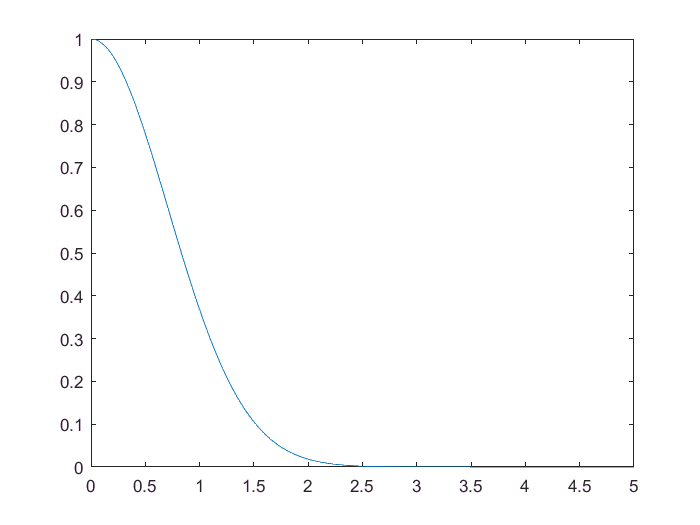

clear all; clc;
t = chebfun(@(t) t, [0 5]);
f = exp(-t.^2);
plot(f);

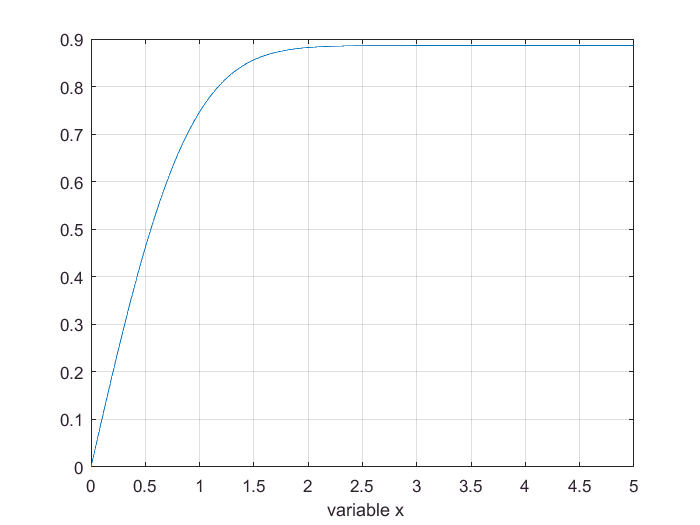

Ix = cumsum(f);    % indefinite integral
plot(Ix); grid on  % compare to the definite integral
xlabel(' variable x')